# Use T_mean change rate to filter out non (quasi-) stationary points

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\processed data");
addpath(fpath,dpath)

load 'processed data'\preprocessed\tableStruct_Stepped.mat
load 'processed data'\preprocessed\tableStruct_Plateau.mat
sensor_position = 97.5:7.5:270;

tableStruct4 = [tableStruct_Stepped,tableStruct_Plateau]; % 3x stepped + 1x plateau

### Calculate T_mean change rate & Store in separate field

for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    tableStruct4(i).avgT_changeRate = avgT_changeRate(t);
end
tableStruct4 % check

tableStruct4 = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate


### Plot T_mean change rate

data_10MPa_1.00h_Oil_20_deg_Stepped


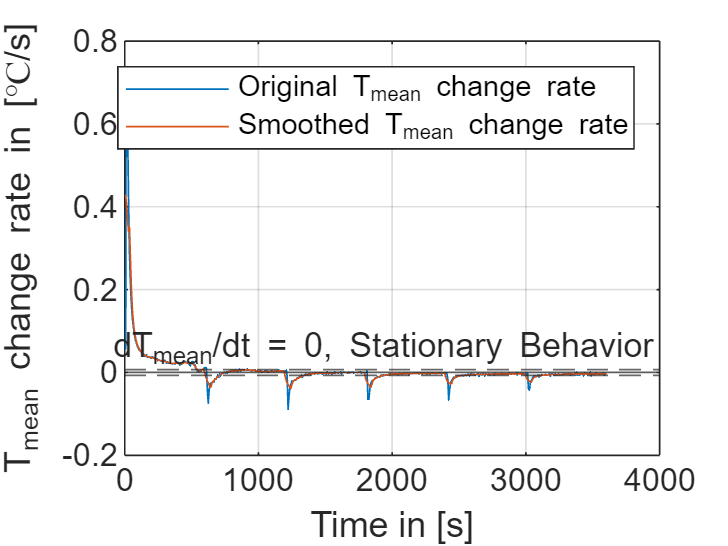

data_10MPa_1.00h_Oil_60_deg_Stepped


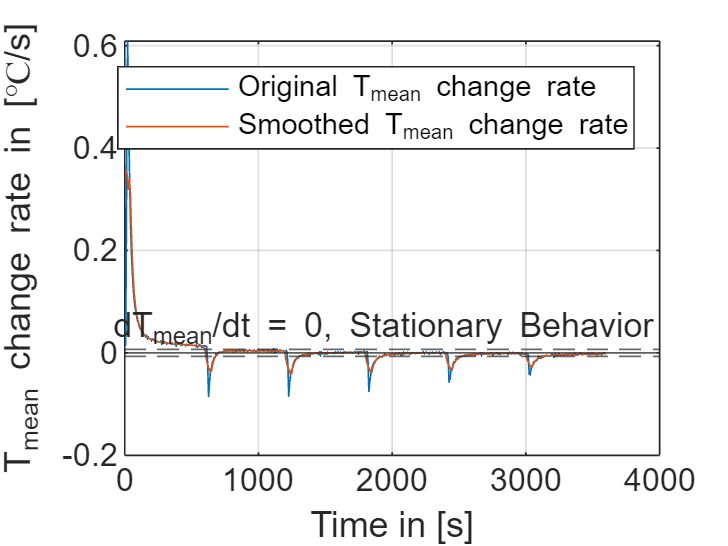

data_15MPa_1.00h_Oil_60_deg_Stepped


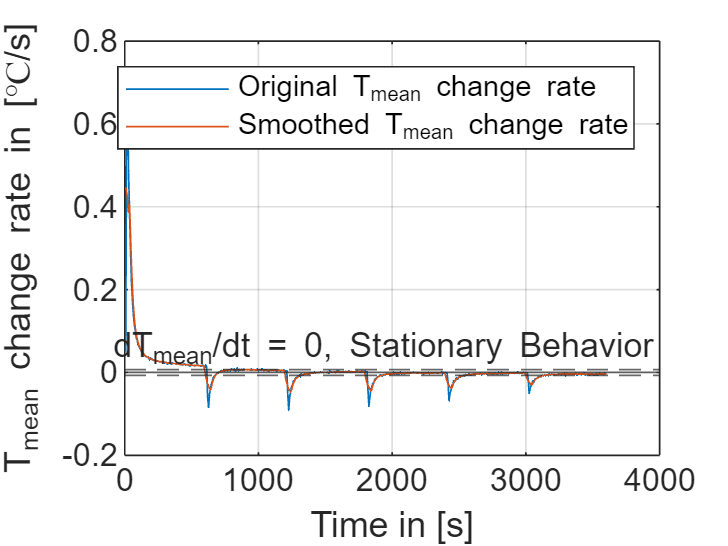

data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


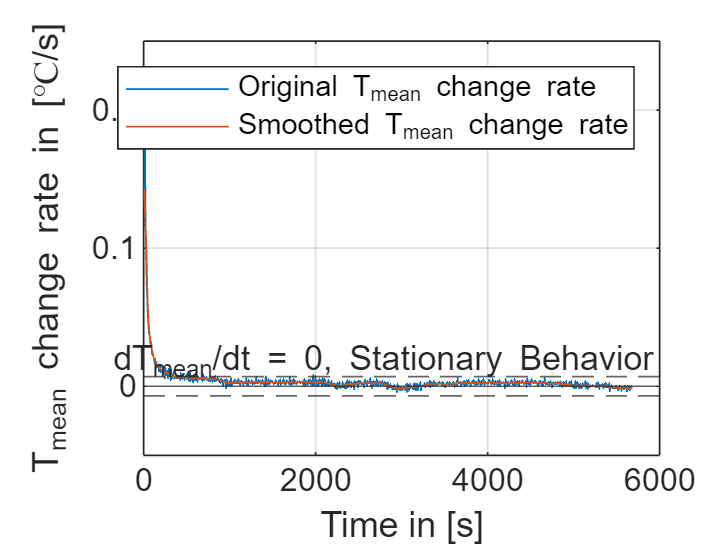

for i = 1:numel(tableStruct4) 
    e = tableStruct4(i);
    disp(e.tableName)
    
    % 对avgT_changeRate进行标准化：
    %avgT_changeRate_standardized = zscore(e.avgT_changeRate);
    
    % plot original non standardized data
    figure;
    plot(e.tableContents.timeStamp(2:end)*3600,e.avgT_changeRate)
    grid on, hold on

    % plot original and smoothed data (k = )
    avgT_changeRate_smoothed = smoothdata(e.avgT_changeRate,"movmean",7);
    plot(e.tableContents.timeStamp(2:end)*3600,avgT_changeRate_smoothed)
    hold off

    yline(0,'-','dT_{mean}/dt = 0, Stationary Behavior')
    ylabel("T_{mean} change rate in [℃/s]")
    xlabel("Time in [s]")

    % choose a threshold (for the smoothed change rate)
    %ylim([-0.02,0.02])
    threshold = 0.007; % [℃/s]
    yline([-threshold, threshold],'--')
    legend("Original T_{mean} change rate","Smoothed T_{mean} change rate")
end

### Filter out all data points whose T_mean change rate exceed the threshold

for i = 1:numel(tableStruct4)
    e = tableStruct4(i);
        
    % smooth the avgT_changeRate vector（k=5）
    avgT_changeRate_smoothed = smoothdata(e.avgT_changeRate,"movmean",4);
    
    % delete the first row to match the dimensions of avgT_changeRate vector
    tableStruct4(i).tableContents(1,:)=[];   
    
    % filtering
    rowsToDelete = [];
    for j = 1:length(avgT_changeRate_smoothed)
        if abs(avgT_changeRate_smoothed(j)) > threshold 
            rowsToDelete(end+1) = j; % delete the jth row
        end
    end
    
    tableStruct4(i).tableContents(rowsToDelete,:)=[]; % delete the rows

end
tableStruct4 % display, saved as 'processed data'\change_rate_filtered\tableStruct4.mat

tableStruct4 = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate


### Visualize the Results

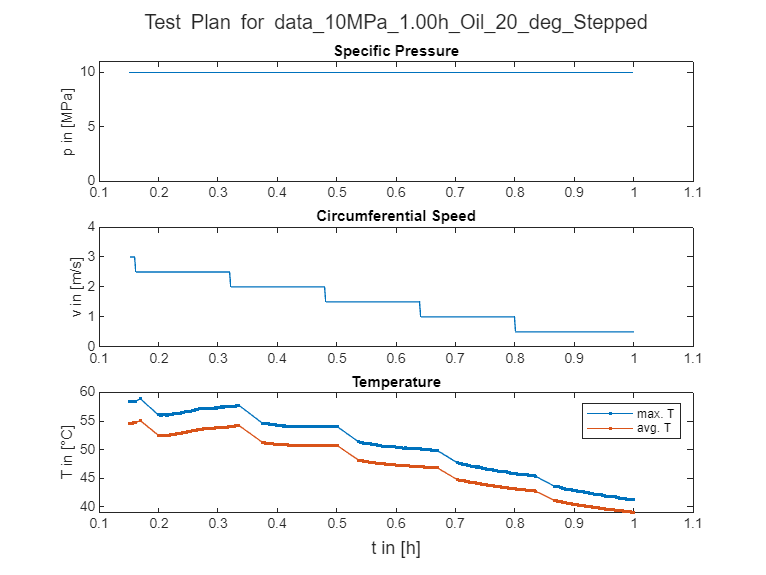

The documented max. T reached 58.875 ℃.


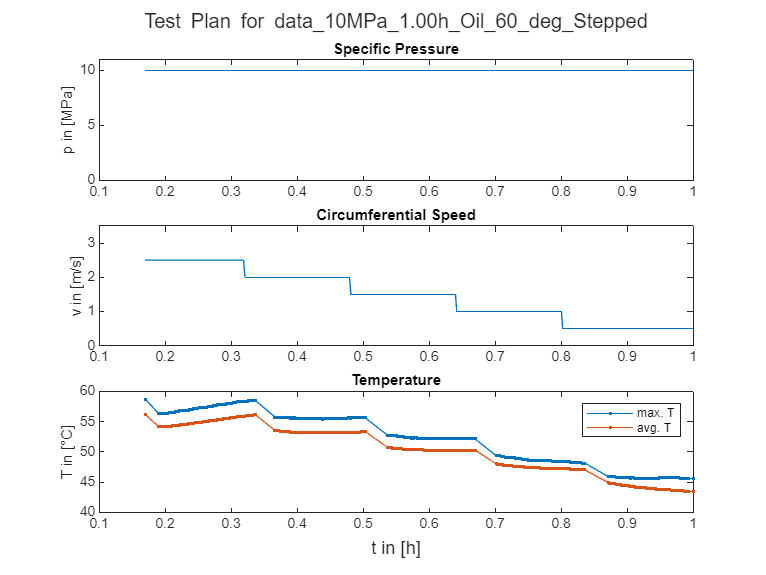

The documented max. T reached 58.625 ℃.


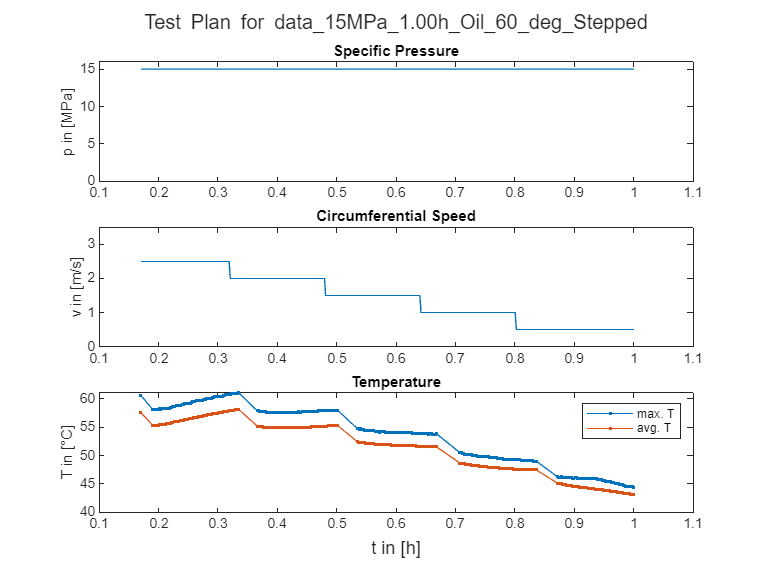

The documented max. T reached 61.125 ℃.


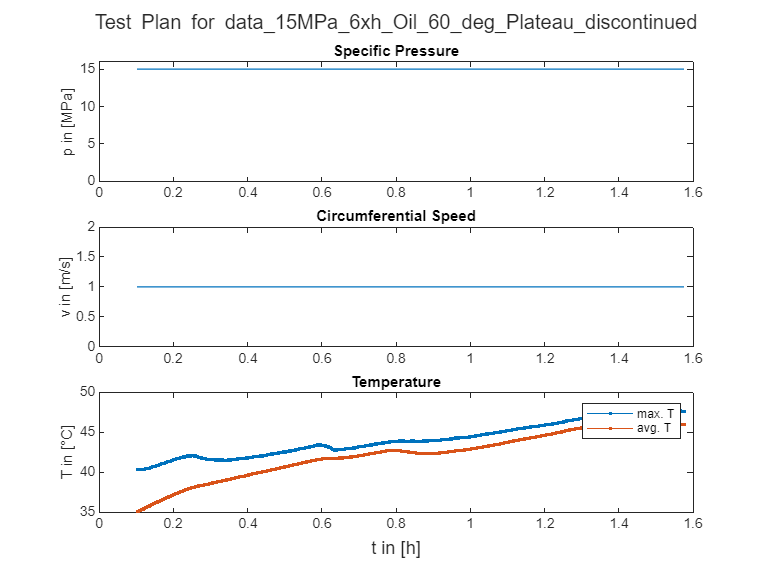

The documented max. T reached 47.75 ℃.


load 'processed data'\change_rate_filtered\tableStruct4.mat
for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    %% Test Plan 可视化
    testplan_visualization(t); 

    %% 时间截面动画
    timeCrossSection_animation(sensor_position,t,1);

    %% 最大值位置动画
    maxT_position_animation(sensor_position,t);
end

# Use the position of T_max to filter out non-usable points

### Filter out all cases where T_max do not lie in the range of φ = 180°~270°

data_10MPa_1.00h_Oil_20_deg_Stepped


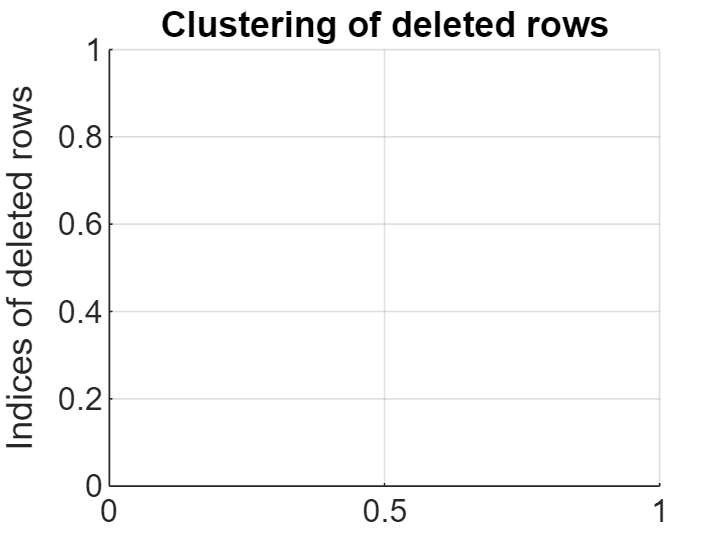

data_10MPa_1.00h_Oil_60_deg_Stepped


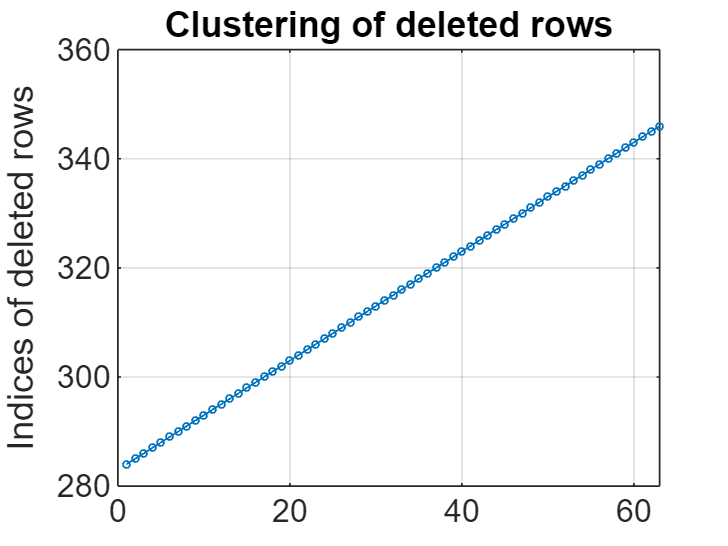

data_15MPa_1.00h_Oil_60_deg_Stepped


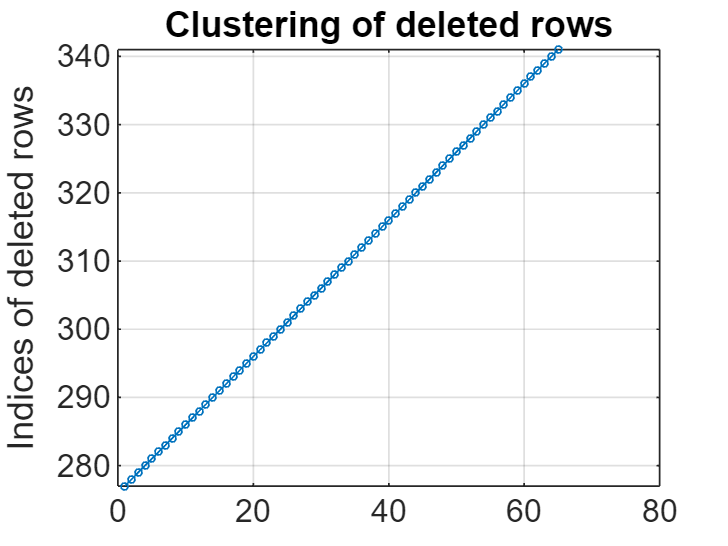

data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


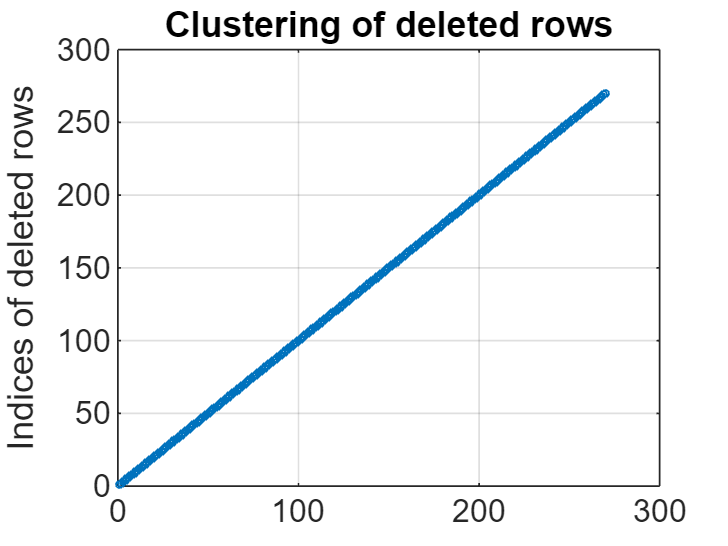

load 'processed data'\change_rate_filtered\tableStruct4.mat
for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    disp(tableStruct4(i).tableName)
    filtered_tbl = positionFilter(t); % with clustering of deleted rows
    tableStruct4(i).tableContents = filtered_tbl; % update
end

tableStruct4 % display, saved as 'processed data'\filtered_final\tableStruct4.mat

tableStruct4 = 1×4 struct array with fields:
    tableName
    tableContents
    avgT_changeRate


### Visualize the Results

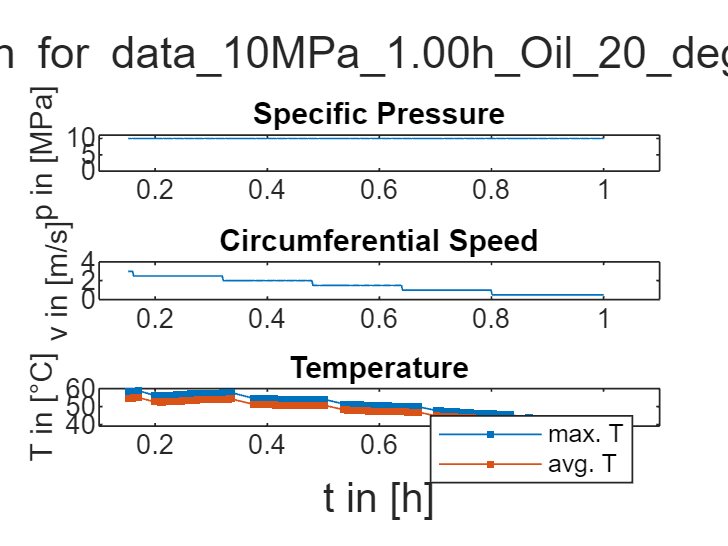

The documented max. T reached 58.875 ℃.


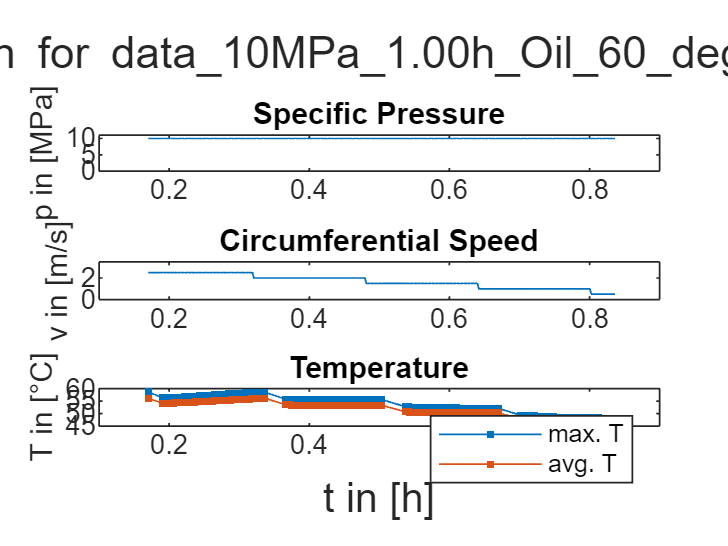

The documented max. T reached 58.625 ℃.


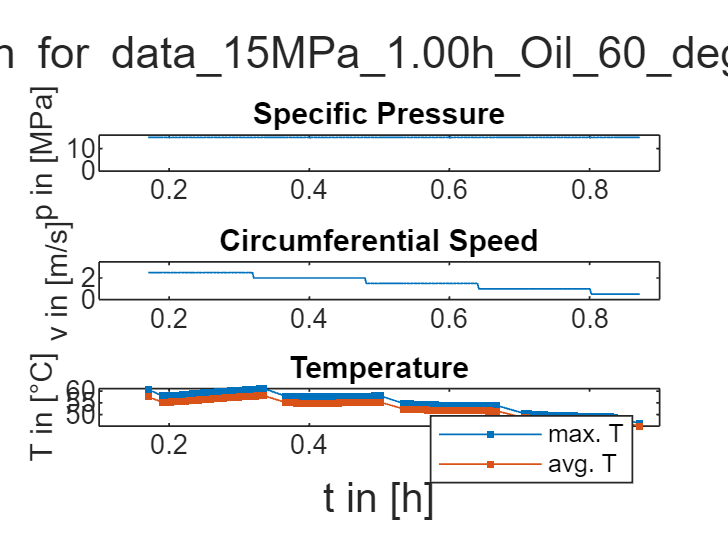

The documented max. T reached 61.125 ℃.


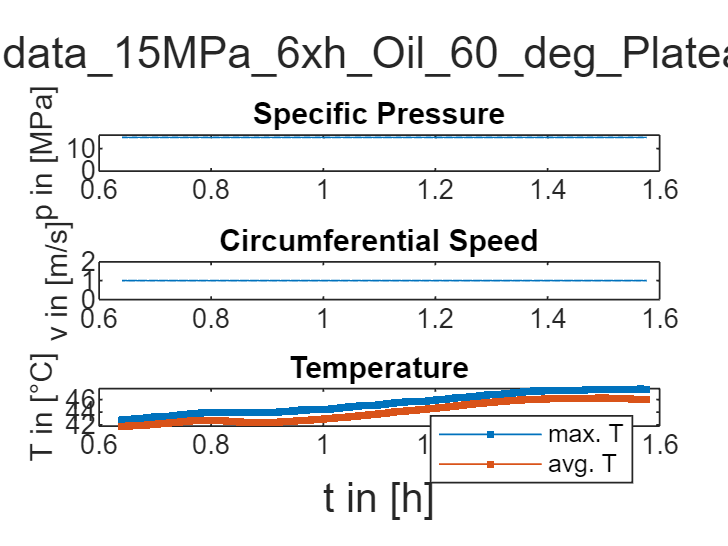

The documented max. T reached 47.75 ℃.


load 'processed data'\filtered_final\tableStruct4.mat
for i = 1:numel(tableStruct4)
    t = tableStruct4(i).tableContents;
    %% Test Plan 可视化
    testplan_visualization(t); 

    %% 时间截面动画
    %timeCrossSection_animation(sensor_position,t,1);

    %% 最大值位置动画
    %maxT_position_animation(sensor_position,t);
end